clc, clear
% 读取视频文件
v = VideoReader('balls.mp4');

% 初始化参数
numFrames = v.NumberOfFrames;
numGaussians = 3; % 高斯分布的数量
frame = rgb2gray(read(v, 1));
[height, width] = size(frame);
weights = ones(height, width, numGaussians) / numGaussians; % 混合权重
means = random('Normal', 0, 1, [height, width, numGaussians]); % 均值
variances = ones(height, width, numGaussians); % 方差
alpha = 0.01; % 学习率
sqrt2pi = sqrt(2 * pi); % 提取出来作为一个常数

% 训练
for t = 1:numFrames
    frame = double(rgb2gray(read(v, t)));

    % 计算距离
    d = abs(frame - means);
    % 更新权重
    weights = (1 - alpha) * weights + alpha * (d < 2.5 * sqrt(variances));
    % 更新均值和方差
    idx = d < 2.5 * sqrt(variances);
    p = alpha ./ (sqrt2pi * variances); % 使用点除来进行元素级的除法
    means = (1 - p) .* means + p .* frame;
    variances = (1 - p) .* variances + p .* (frame - means) .^ 2;
end

[~, order] = max(weights, [], 3);
background = zeros(height, width);

for i = 1:numGaussians
    idx = order == i;
    [row, col] = find(idx);
    linearIdx = sub2ind([height, width, numGaussians], row, col, i*ones(size(row)));
    background(idx) = means(linearIdx);
end

% 背景检测
foreground = zeros(height, width);

for i = 1:numGaussians
    idx = order == i;
    [row, col] = find(idx);
    linearIdx = sub2ind([height, width, numGaussians], row, col, i*ones(size(row)));
    foreground(idx) = abs(frame(idx) - background(idx)) > 2.5 * sqrt(variances(linearIdx));
end

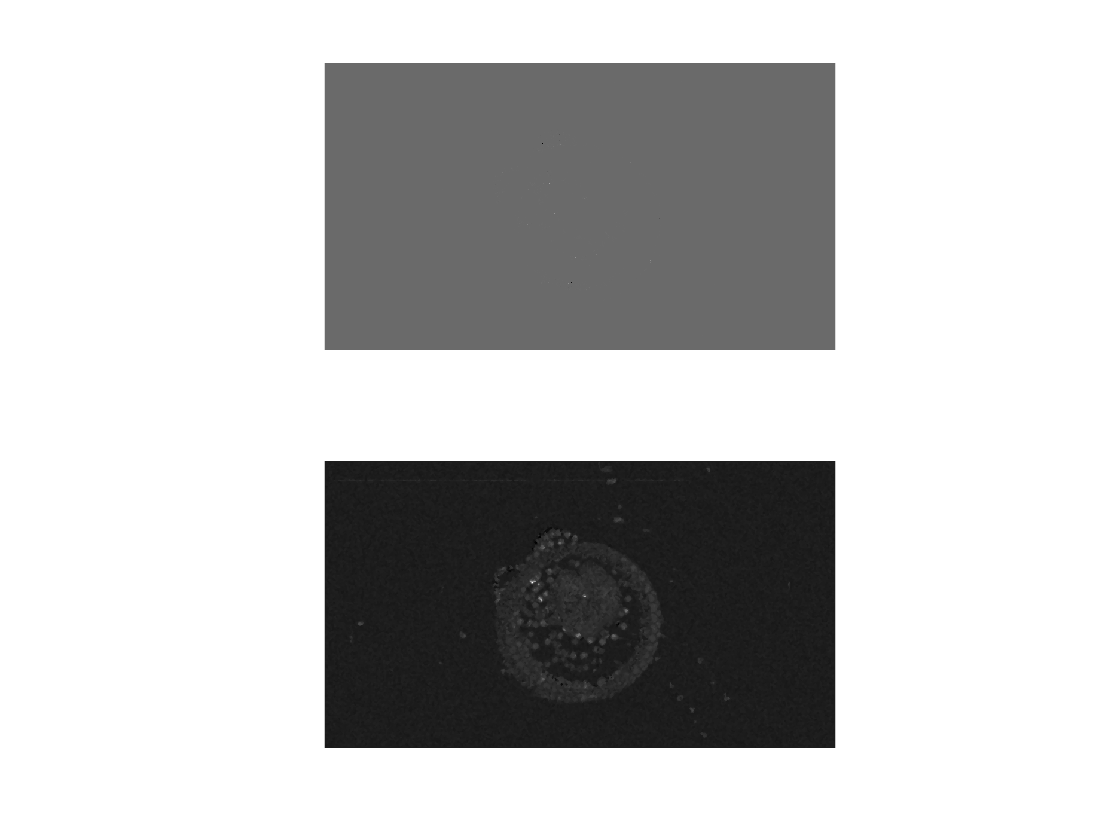


subplot(2,1,1)
imshow(background, []);

subplot(2,1,2)
% 使用中值滤波器降低椒盐噪声
track_filtered =medfilt2(medfilt2(medfilt2(background)));

% 显示结果
imshow(track_filtered, []);